%% Exercise 1
clear; close all; clc;

% System Matrices
Ad = [0.1139   -0.2238    0.2908   -0.0019;
     -0.1119    0.2736    0.2459   -0.0010;
      0.0291    0.0492    0.5467    0.0002;
      95.6006   98.9583 -101.4174    0.0302];

Bd = [0.0130   -0.0091;
     -0.0091    0.0114;
      0.0020    0.0014;
      0.4932    0.3824];

Nd = Bd;  % Assume process noise matrix Nd = Bd

Cd = [0 0 0 1; 0 0 1 0];  % Output matrix

% Process Noise Covariance (R1)
R_1 = 222222.2 * eye(2);

% Measurement Noise Covariance (R2)
sigma_v_load = 0.06 * 11043.978 * sqrt(2) * 10^3 / 3;
sigma_i_load = 0.06 * 4.4782e+003 / 3;

% R_2 = [sigma_v_load^2, 0.5 * sqrt(sigma_v_load^2 * sigma_i_load^2);
%        0.5 * sqrt(sigma_v_load^2 * sigma_i_load^2), sigma_i_load^2];

R_2 = [48787.78 73.99;
    73.99 0.4489];

% State-Space System (Extended Input: Bd and Nd)
Plant = ss(Ad, [Bd Nd], Cd, zeros(2,4),0.005);  % 2 outputs, 4 inputs

%% Kalman Filter Design
[kalmf, L, P] = kalman(Plant, R_1, R_2);

% Observer Eigenvalues
A_obs = Ad - L * Cd;
observer_eigenvalues = eig(A_obs);
eigenvalue_magnitudes = abs(observer_eigenvalues);
is_stable = all(eigenvalue_magnitudes < 1);
disp(observer_eigenvalues);

  -0.0419 + 0.4269i
  -0.0419 - 0.4269i
   0.3888 + 0.0000i
   0.1619 + 0.0000i



disp('Are all observer eigenvalues stable (< 1)?');

Are all observer eigenvalues stable (< 1)?


disp(is_stable);

   1



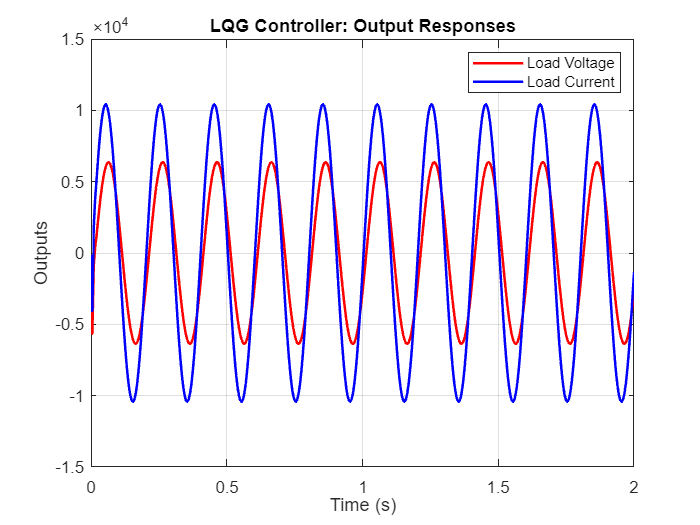


%% LQR Controller Design
Q_x = 50 * eye(4);    % State weighting matrix
Q_u = 0.01 * eye(2);  % Input weighting matrix (dimension matches Bd)

[K, S, P] = dlqr(Ad, Bd, Q_x, Q_u);

%% LQG Controller (LQR + Kalman Filter)
rlqg = lqgreg(kalmf, K);

%% Simulation
A = 1e3;            % Input amplitude
w = 2 * pi * 5;     % Input frequency
t = 0:0.005:2;      % Simulation time

% Input signal (assumed sinusoidal disturbance)
u_input = [A * cos(w * t); A * sin(w * t)];  % Control input for two inputs

% Simulate the LQG system
[y, t_out, x] = lsim(rlqg, u_input', t);

%% Plot Results
figure;
plot(t_out, y(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(t_out, y(:, 2), 'b', 'LineWidth', 1.5);
title('LQG Controller: Output Responses');
xlabel('Time (s)');
ylabel('Outputs');
legend('Load Voltage', 'Load Current');
grid on;

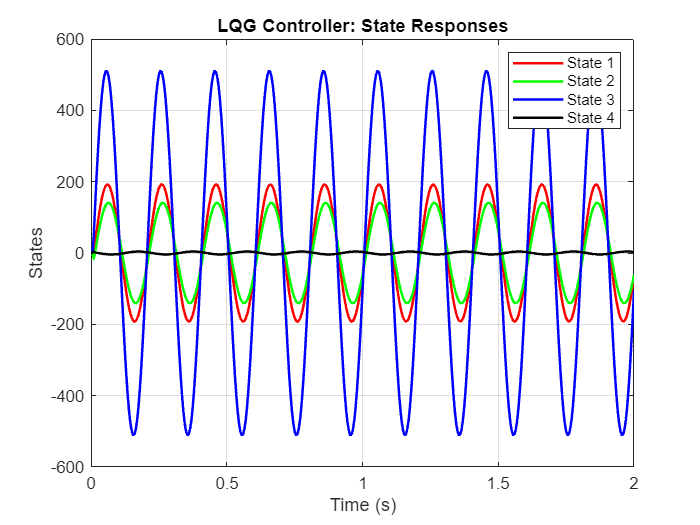


figure;
plot(t_out, x(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(t_out, x(:, 2), 'g', 'LineWidth', 1.5);
plot(t_out, x(:, 3), 'b', 'LineWidth', 1.5);
plot(t_out, x(:, 4), 'k', 'LineWidth', 1.5);
title('LQG Controller: State Responses');
xlabel('Time (s)');
ylabel('States');
legend('State 1', 'State 2', 'State 3', 'State 4');
grid on;